# FM Modulate and Demodulate Sinusoidal Signal

Set the sample rate and carrier frequency. Generate a time vector having a duration of 0.2 s.

fs = 10000; 
fc = 200;  
t = (0:1/fs:0.2)';

Create a sinusoidal signal.

x = 2*sin(2*pi*60*t);

Set the frequency deviation to 50 Hz.

fDev = 50;

Frequency modulate `x`.

y = fmmod(x,fc,fs,fDev);

Demodulate `z`.

z = fmdemod(y,fc,fs,fDev); % Demodulate both channels.

Plot the original and demodulated signals.

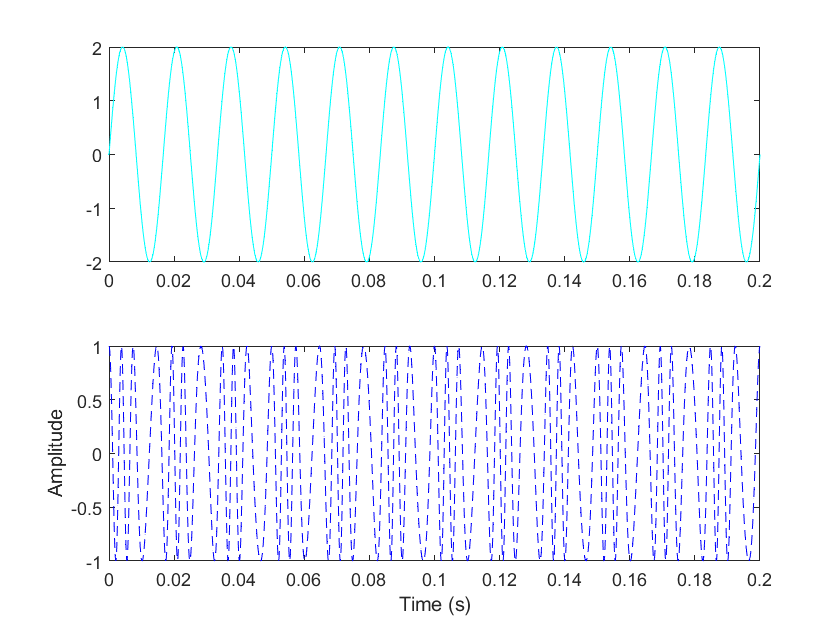

subplot(2,1,1)
plot(t,x,'c')
subplot(2,1,2)
plot(t,y,'b--');
xlabel('Time (s)')
ylabel('Amplitude')

%legend('Original Signal','Demodulated Signal')

The demodulated signal is well aligned with the original. 

*Copyright 2012 The MathWorks, Inc.*